%read path
clear
clc
path = 'C:\Users\thamr\OneDrive\Desktop\finalMatlab\dataset-3a.xlsx';
Q1a = readmatrix(path,'Sheet','Q1A');
QHS1 = readmatrix(path,'Sheet','QH_S1');
QHS3 = readmatrix(path,'Sheet','QH_S3');

x = 1:length(Q1a(1:60,1));
y = Q1a(:,2);
x = x(~isnan(x));
y = y(~isnan(y));
y = y';

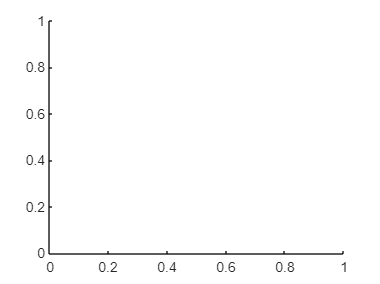

%พอตค่าที่เก็บไว้
hold off

plot(x,y,'o');

Error using plot
Vectors must be the same length.

xlabel("Height_1")
ylabel("Discharge_1")
title("Station1")
grid on

% linear fit
xTest  = Q1a(:,1)';
    mdl = fitlm(x',y');
    nv = predict(mdl,xTest');
    nv = nv';

hold on
plot(length(xTest),nv,'-','Color','r')
v = 1:length(xTest);
% R squared 
R_squared = 1 - sum((v - nv).^2) / sum((v - mean(v)).^2);
% Mean Absolute Error (MAE) calculation
MAE = sum(abs(v - nv))/length(v);
% Mean Squared Error (MSE) calculation
MSE = (sum((v - nv).^2))/(length(v));
fprintf("R_squared : %.5f",R_squared);
fprintf("MSE : %.4f",MSE);
hold off

nv = nv';
xlswrite(path,nv(61:65,1),1,'B62');

plot(x,y,'*');
hold on
plot(xTest,nv)
nv = nv';
newNv = nv(1,61:65);
plot(xTest(1,61:65),newNv,'o',Color='r')
xlabel("Day")
ylabel("Discharge")
legend("Height_1","predictHieght_1","Hieght_1(Day60-65)")
grid on
v = 1:length(xTest);
% R squared 
R_squared = 1 - sum((v - nv).^2) / sum((v - mean(v)).^2);
% Mean Absolute Error (MAE) calculation
MAE = sum(abs(v - nv))/length(v);
% Mean Squared Error (MSE) calculation
MSE = (sum((v - nv).^2))/(length(v));
fprintf("R_squared : %.5f",R_squared);
fprintf("MSE : %.4f",MSE);
nv = nv';

%เก็บข้อมูลลงในตัวแปร โดยทุก row แต่เลือก col
%ทำนาย Q1
hData1 = QHS1(:,1);
qData1 = QHS1(:,2);
x = hData1';
y = qData1';

%พอตค่าที่เก็บไว้
hold off
plot(x,y,'o');
xlabel("Height_1")
ylabel("Discharge_1")
title("Station1")
grid on

 %neural network model = md
    hLS = 30;
    net = feedforwardnet(hLS);
    mdl = train(net,x,y);
    nv = mdl(x);

%แสดงค่าพอตกับ model
hold on
plot(x,nv,'-','Color','r')
v = y;
% R squared 
R_squared = 1 - sum((v - nv).^2) / sum((v - mean(v)).^2);
% Mean Absolute Error (MAE) calculation
MAE = sum(abs(v - nv))/length(v);
% Mean Squared Error (MSE) calculation
MSE = (sum((v - nv).^2))/(length(v));
fprintf("R_squared : %.5f",R_squared);
fprintf("MSE : %.4f",MSE);
hold off

%คำนาย 60 วันจากค่าความสู.ของระดับน้ำสถานีแรก
H1aTest = readmatrix(path); %Q1
H1aTest = H1aTest(:,2);
H1aTest = H1aTest(~isnan(H1aTest))';
for i=1:length(H1aTest)
     predict = sim(mdl,H1aTest);
end
predict = predict(~isnan(predict));

%เขียนลง Sever
predictWrite = predict(1,61:end)';
xlswrite(path,predictWrite,1,'C62');

%พอตกราฟค่าPredict เปรียบเทียบกับ ค่าจริงที่วัดได้พร้อมทำนายวันที่ 55-60
hold off
Q1a = readmatrix(path);
yTest = Q1a(:,3);
yTest = yTest(~isnan(yTest))';
xTest = Q1a(:,2);
xTest = xTest(~isnan(xTest))';
Day = 1:length(xTest);
plot(Day,yTest,'-',Color='b')
hold on
plot(Day(:,1:60),predict(:,1:60),'-',Color='r')
plot(Day(:,61:65),predict(:,61:65),'*',Color='r')
xlabel("Day")
ylabel("Discharge")
legend("Height_1","predictDischarge_1","Discharge(Day55-60)")
grid on

 nvAfter = predict(~isnan(predict));
 vAfter = yTest;
 % R squared 
 R_squared_test = 1 - sum((vAfter - nvAfter).^2) / sum((vAfter - mean(vAfter)).^2);
 % Mean Absolute Error (MAE) calculation
 MAE_test = sum(abs(vAfter - nvAfter))/length(vAfter);
 % Mean Squared Error (MSE) calculation
 MSE_test = (sum((vAfter - nvAfter).^2))/(length(vAfter));
 fprintf("R_squared predict : %.5f",R_squared_test);
 fprintf("MSE predict : %.4f",MSE_test);
 for i = 1:5
    fprintf("Predict by linear day %d : %.2f\n",i+60,predict(:,i+60))
 end

